# Práctica 2: Análisis de métodos de control de complejidad

## Abstract

Tomando una distribución generada a  partir de la función de tres tangentes hiperbólicas vista en clase, se  deberá estudiar el comportamiento de las distribuciones del Error de  Generalización, Error Empírico y Modelo óptimo seleccionado en relación  al tamaño de las muestras. Como funciones aproximadoras utilizaremos el  conjunto de funciones polinomiales.

## Conjunto de datos

### Generación de datos teóricos (Población)

Para generar la función teórica se ha generado una muestra de 1000 ejemplos. Con ella calcularemos el ruido que usaremos para generar las muestras para realizar los experimentos.

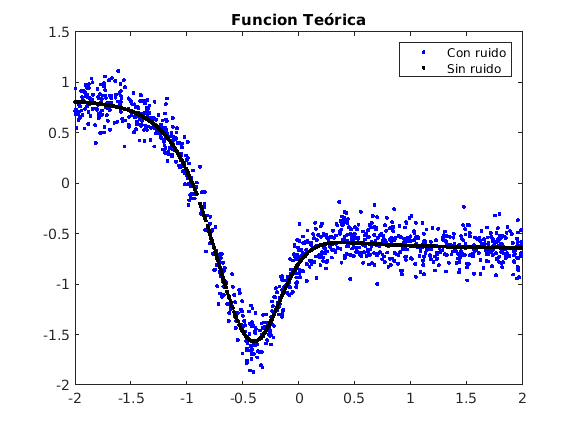

clear all, close all

num_points = 1000;

%Definimos x e y.
x=4*(rand(1,num_points)-0.5);
yok=1.8 *tanh(3.2 * x + 0.8)- 2.5 * tanh(2.1 * x + 1.2)-0.2 * tanh(0.1 * x-0.5); 

%Definimos ruido y se lo añadimos a nuestra y.
RUIDO=0.2 * std(yok);
yruido=RUIDO * randn(size(yok));
y=yok+yruido;

plot(x,y,'.b'); hold on
plot(x,yok,'.k');  hold off
legend('Con ruido','Sin ruido');
title('Funcion Teórica')

### Partición de la muestra

Usaremos el método Hould out, para ello dividiremos la muestra en 2 partes. Una de ellas con el 70% de los datos para entrenar y otra con el 30% restante para validar. Que tengan un número diferente de datos nos permitirá generalizar mejor así diminuyendo la probabilidad de que los datos de entrenamiento y validación sean coincidentes o representen la misma parte de la función al generarlos mediante una distribución uniforme.

 A parte el error no sería tan representativo ya que si el conjunto de entrenamiento es menor o igual,  tendría en cuenta un menor/igual número de ejemplos para ajustar la complejidad (entrenamiento), y por lo tanto estaríamos dándole al error de generalización un mayor valor o importancia de forma implícita.

Intuitivamente se puede observar que si tuvieramos una muestra de 10 ejemplos, realizaramos el entrenamiento solo con 2 de ellos, en primera instancia, y obviando que la representación de la función es totalmente dudosa con solo 2 ejemplos, la complejidad no podría ser superior a dos, y en segunda instancia, al tener 8 ejemplos que no se han tenido en cuenta si quiera para obtener nuestra hipótesis para validarlo, existe una gran probalidad de que el error de generalización sea extremadamente alto (muestra de entrenamiento no representativa) ya que por cada ejemplo se irá acumulando ese error. No olvidemos que el objetivo del conjunto de validación es validar nuestro modelo.

Con el estándar 70-30 nos aseguramos una cantidad de ejemplos ( más de la mitad) suficiente como para representar correctamente nuestra función y un conjunto de ejemplos para validar lo suficientemente grande como para generalizar, pero no lo suficiente como para afectar negativamente al error de generalización.

Utilizaremos una muestra de tamaño 50. Es decir 35 datos para entrenar y 15 datos para validar. Con ello nos aseguraremos de que al hacer una división por porcentajes, la partición de validación sea lo suficientemente grande como para representar la función subyacente, pero no lo suficientemente grande sobreajustar el modelo desde un inicio. 

%Definimos numero de puntos.
n_sample = 50;
n_valid = 0.3 * n_sample;
n_train = n_sample - n_valid;


## Análisis del error de Generalización/Empírico

Utilizaremos el análisis del error empírico y el error de generalización para, mediante el estudio de las tendencias de ambos, poder un modelo de predicción. Fijaremos la complejidad máxima a 15 debido a que nuestras muestras no son relativamente grandes intentando así evitar el overfitting. Además teniendo en cuenta la función subyacente que al ser teórica es conocida, sabemos que no será mayor que 15 así que nos evitamos computaciones extra.

### Método de validación

Para analizar el error utilizaremos el método de validación Random Sampling, ya que al trabajar con una muestra teórica podemos generar cuantos datos nos plazca, pudiendo repetir el experimento las veces que queramos, disminuyendo la alta variaza de la la distribución de errores que genera el método Hold out y también debido a que trabajamos con muestras pequeñas, ya que uno de los grandes inconvenientes de este método es la que es computacionalmente costoso, no siendo este el caso.

### Random Sampling

Repetiremos el experimento 250 veces. El número de experimentos se ha adjustado de manera empírica, observando el error, hasta elegir un número de experimentos que suavizara las curvas, es decir que minimizara el efecto de la aleatoriedad suficiente como para poder analizar las tendencias de ambos errores.

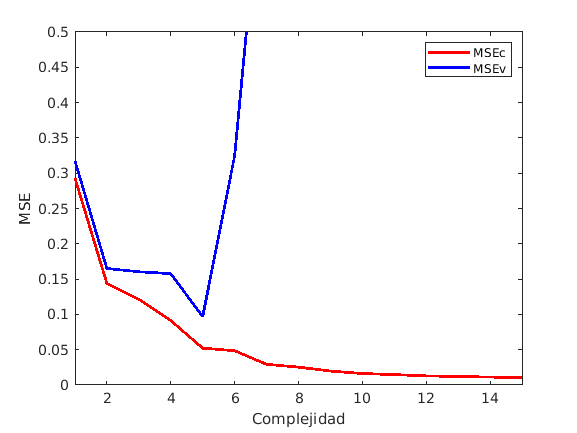

% Definimos complejidad máxima
max_complex = 15;
% Definimos número de experimentos
n_experiments = 1000;
best_model_local = zeros(1, max_complex);

for t=1:n_experiments
    %Definimos x e y.
    clear xsample
    clear ysample
    
    xtrain = 4*(rand(1,n_train)-0.5);
    ytrain = 1.8 * tanh(3.2 * xtrain + 0.8)- 2.5*tanh(2.1* xtrain + 1.2)-0.2*tanh(0.1* xtrain -0.5);
    ytrain = ytrain + RUIDO*randn(1, n_train);
        
    xtest = 4*(rand(1,n_valid)-0.5);
    ytest = 1.8*tanh(3.2*xtest + 0.8)- 2.5*tanh(2.1*xtest + 1.2)-0.2*tanh(0.1*xtest-0.5);
    ytest = ytest + RUIDO*randn(1, n_valid);


    for i=1:max_complex
        p(t, i)={polyfit(xtrain, ytrain,i)};
        yest1=polyval(p{t, i},xtrain);
        yest2=polyval(p{t, i},xtest);
        errorE(t,i)= ecm(yest1 - ytrain);
        errorG(t,i)= ecm(yest2 - ytest);
    end
    
end

errorME=mean(errorE);
errorMG=mean(errorG);

for i=1:max_complex
    lineal_values = [p{:,i}];
    mat_model= reshape(lineal_values', [i + 1, n_experiments])';
    mean_model(i) = {mean(mat_model)};
end

xx=1:max_complex;
plot(xx, errorME, '-r', 'LineWidth',2),hold on;
plot(xx, errorMG, '-b', 'LineWidth',2)
legend('MSEc','MSEv');
xlim([1 max_complex])
ylim([0 0.5])
xlabel('Complejidad') 
ylabel('MSE') 
hold off;

## Selección del modelo

Para seleccionar el modelo se utilizará como criterio para escoger el menor error de generalización. Escogiendo, por tanto el modelo con menor error en el error de generalización medio de todos nuestros experimentos.

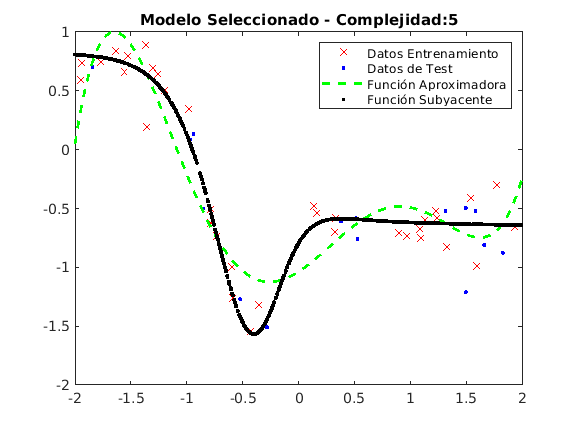

xmodel = linspace(-2, 2, 200);
[~, best_model] = min(errorMG); 
h = mean_model{best_model};
ymodel_estimated = polyval(h, xmodel);

plot(xtrain,ytrain,'xr'); hold on
plot(xtest,ytest,'.b');
plot(xmodel, ymodel_estimated, '--g', 'LineWidth',2)
plot(x,yok,'.k'); 
title(['Modelo Seleccionado - Complejidad:', num2str(best_model) ])
legend('Datos Entrenamiento','Datos de Test', 'Función Aproximadora', 'Función Subyacente');


hold off

## Análisis de el error con respecto a la variación del tamaño muestral

Para analizar el error con respecto a la variación del tamaño de la muestra, iniciaremos con un tamaño muestral igual al de la máxima complejidad si es menor probocaría un mal ajuste polinómico y distorsionaría los errores, luego iremos aumento la muestra de 20 hasta 500 para tener una visión más general de la tendenciaas de los errores. Se establece un paso 20 para que el manejo de la granularidad no genere picos innecesarios, esto se ha comprobado de manera empírica aumentando y disminuyendo el paso.

El error convergería en la varianza del ruido : 0.1370.^2

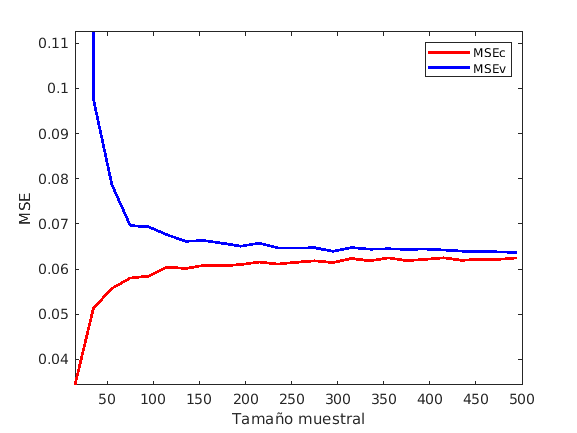

pob_ini = max_complex;
step = 20;
max_pob = 500;


sample_size=pob_ini:step:max_pob; % la muestra no puede ser menor que la complejidad del modelo

clear ErrorG
clear ErrorE


for t=1:250
    for i=1:length(sample_size)
        
        xtrain=4*(rand(1,sample_size(i))-0.5);
        ytrain=1.8*tanh(3.2*xtrain + 0.8)- 2.5*tanh(2.1*xtrain + 1.2)-0.2*tanh(0.1*xtrain-0.5);
        ytrain= ytrain + RUIDO*randn(1, sample_size(i));
   
        
        xtest=4*(rand(1,sample_size(i))-0.5);
        ytest=1.8*tanh(3.2*xtest + 0.8)- 2.5*tanh(2.1*xtest + 1.2)-0.2*tanh(0.1*xtest-0.5);
        ytest= ytest + RUIDO*randn(1, sample_size(i));
   
        
        h = polyfit(xtrain,ytrain, best_model);

        ErrorG(t,i)=ecm(ytest-polyval(h,xtest));
        ErrorE(t,i)=ecm(ytrain-polyval(h,xtrain));
        

    end
end


ErrorG=mean(ErrorG,1);
ErrorE=mean(ErrorE,1);

plot(sample_size,ErrorE,'-r','LineWidth',2); hold on
plot(sample_size,ErrorG,'-b','LineWidth',2); 
legend('MSEc','MSEv');
axis([pob_ini, max_pob, min(ErrorE), max(ErrorE) + 0.05]);
legend('MSEc','MSEv');
xlabel('Tamaño muestral') 
ylabel('MSE')
hold off